# Class 4 Homework - Xinyi (Cynthia) Shen

Student Number: 1005778428

## Problem

Calculate 1 day 99% VaR for Pepsi

- using the historical method

- one parametric method of your choosing

- using 40 years of data from Yahoo! Finance

- Assume you have USD$100,000 in Pepsi stock

How do your numbers compare to what we did in class? If worse, why?

### Download Coke and Pepsi Stock Data

% Use Python's yfinance to download PEP historical stock data for the last 40 years
PEP_data = py.yfinance.download('PEP', pyargs('start', '1984-10-02', 'end', '2024-10-02', 'interval', '1d'));


[*********************100%***********************]  1 of 1 completed


% Convert dataframe to table
TTPEP = table(PEP_data);

% Clean column names and remove unecessary variables, for now
TTPEP = renamevars(TTPEP, "Adj Close", "PEP");
TTPEP = removevars(TTPEP, ["Open","High","Low","Close","Volume"]);

% Key Time Series
t = datetime(TTPEP.Date);
pep = TTPEP.PEP;

% Define the change and % change in KO and PEP
dPEP = diff(pep);
rPEP = diff(pep) ./pep(1:end-1);

% Assume some portfolio value
portfolio_value = 100000; % $100k

### Calculate 1-day 99% VaR for Pepsi using Historical Method

#### 40-year Pepsi

The **historical method** for Value at Risk (VaR) is a non-parametric approach that uses historical returns to estimate the potential future loss of a portfolio over a given time horizon and confidence level.


$$VaR_{\alpha}=-Portfolio\ Value \times Percentile_{\alpha}(Historical\ Returns)$$


hRaR_PEP_40 = prctile(rPEP, 1);
hVaR_PEP_40 = - portfolio_value * hRaR_PEP_40;

fprintf('1-Day 99%% Historical VaR for USD $100k in 40-year Pepsi stock data is: USD $%.2f\n', hVaR_PEP_40);

1-Day 99% Historical VaR for USD $100k in 40-year Pepsi stock data is: USD $3906.26


#### What We Did in Class

T = length(rPEP);
I1Yr = T-1*252:T;
I3Yr = T-3*252:T;
I5Yr = T-5*252:T;

hRaR_PEP_1 = prctile(rPEP(I1Yr), [1]);
hRaR_PEP_3 = prctile(rPEP(I3Yr), [1]);
hRaR_PEP_5 = prctile(rPEP(I5Yr), [1]);

hVaR_PEP_1 = - portfolio_value * hRaR_PEP_1;
fprintf('1-Day 99%% Historical VaR for USD $100k in 1-year Pepsi stock data is: USD $%.2f\n', hVaR_PEP_1);

1-Day 99% Historical VaR for USD $100k in 1-year Pepsi stock data is: USD $3004.08


hVaR_PEP_3 = - portfolio_value * hRaR_PEP_3;
fprintf('1-Day 99%% Historical VaR for USD $100k in 3-year Pepsi stock data is: USD $%.2f\n', hVaR_PEP_3);

1-Day 99% Historical VaR for USD $100k in 3-year Pepsi stock data is: USD $2817.41


hVaR_PEP_5 = - portfolio_value * hRaR_PEP_5;
fprintf('1-Day 99%% Historical VaR for USD $100k in 5-year Pepsi stock data is: USD $%.2f\n', hVaR_PEP_5);

1-Day 99% Historical VaR for USD $100k in 5-year Pepsi stock data is: USD $3523.77


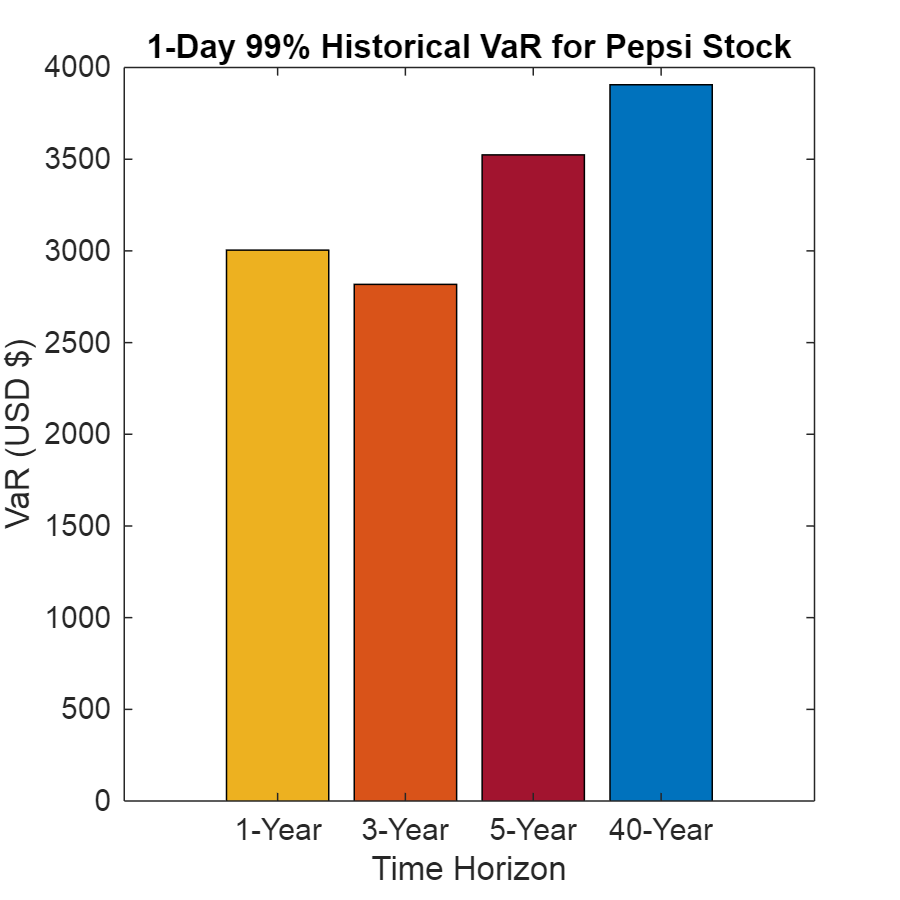

% Time horizons and VaR values
time_horizons = {'1-Year', '3-Year', '5-Year', '40-Year'};
VaR_values = [hVaR_PEP_1, hVaR_PEP_3, hVaR_PEP_5, hVaR_PEP_40];

% Create the bar chart
figure()
set(gcf, 'Position', [0 0 400 400])
b = bar(VaR_values, 'FaceColor', 'flat');

% Set different colors for each bar
b.CData(1,:) = [0.9290 0.6940 0.1250];   % Blue for 40-Year
b.CData(2,:) = [0.8500 0.3250 0.0980];   % Green for 1-Year
b.CData(3,:) = [0.6350 0.0780 0.1840]; % Orange for 3-Year
b.CData(4,:) = [0 0.4470 0.7410];   % Red for 5-Year

% Add labels and title
set(gca, 'XTickLabel', time_horizons);
xlabel('Time Horizon');
ylabel('VaR (USD $)');
title('1-Day 99% Historical VaR for Pepsi Stock');

#### Observation

The 1-day 99% historical VaR for USD$100,000 in **40-year** Pepsi stock data is **higher** than the 1-day 99% historical VaRs for USD$100,000 in **1-year**, **3-year**, and **5-year** Pepsi stock data.

In class, we focused on a shorter time horizon, i.e., 1 year, 3 years, and 5 years to calculate VaR while in my current analysis, I am looking at much longer time horizons like 40 years. Longer time horizons tend to produce larger VaR estimates because they account for more historical volatility, including extreme market events that may not be reflected in shorter periods. Other reasons that account for a higher VaR might be the inclusion of extreme events in the 40-year dataset, which may not have been considered in shorter timeframes.

### Calculate 1-day 99% VaR for Pepsi using Parametric Method of Normal VaR

#### 40-year Pepsi

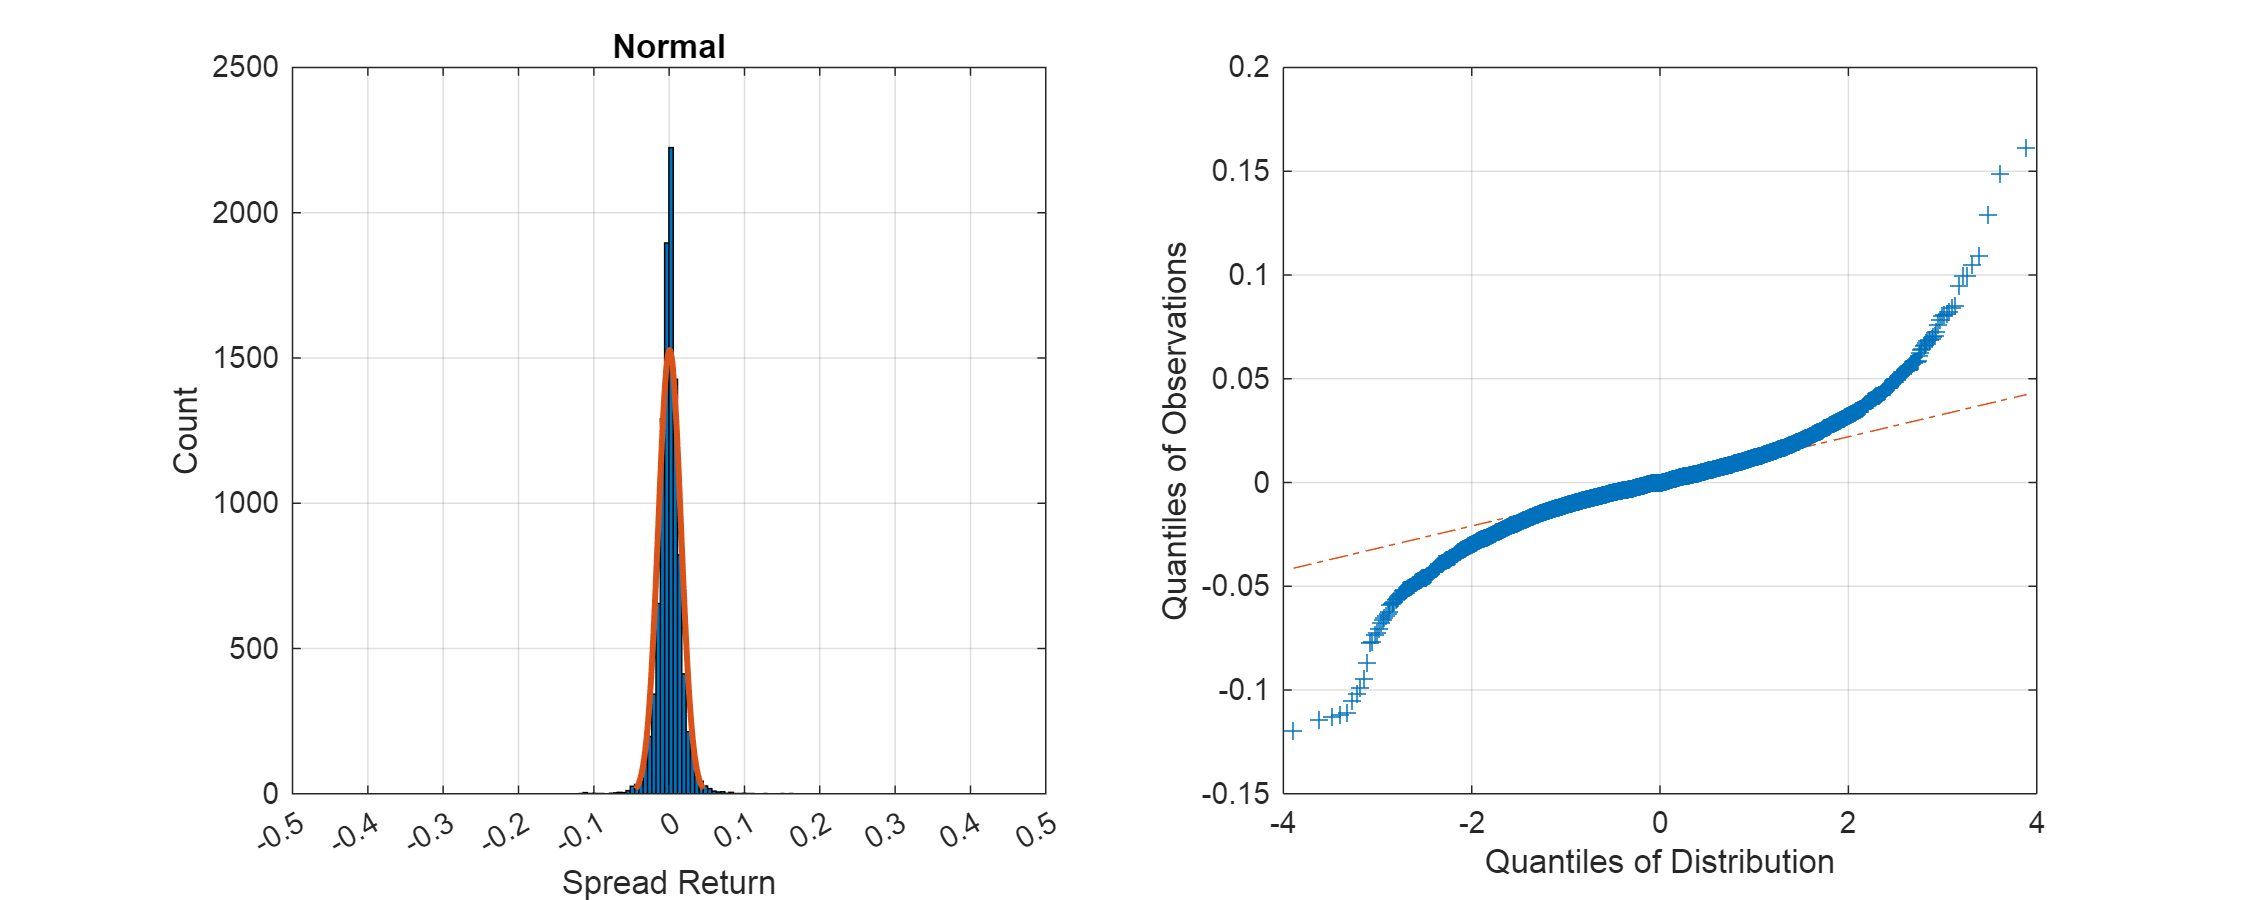

figure()
set(gcf, 'Position', [0 0 1000 400])
 
subplot(1,2,1)
histfit(rPEP,50,'normal')
set(gca,'XTick',-0.5:0.10:0.5)
xlim([-0.50 +0.50])
title('Normal')
ylabel('Count')
xlabel('Spread Return')
grid on
 
subplot(1,2,2)
qqplot(rPEP, makedist("Normal"))
title('')
ylabel('Quantiles of Observations')
xlabel('Quantiles of Distribution')
box on
grid on


% Assuming rPEP contains percentage returns
mu_rPEP = mean(rPEP);  % Mean of returns
sigma_rPEP = std(rPEP);  % Standard deviation of returns

alpha = 0.01;
z_99 = norminv(1 - alpha);  % Z-score for 99% confidence level

% Calculate 1-day 99% Normal VaR for PEP
nRaR_PEP_40 = mu_rPEP - z_99 * sigma_rPEP;
nVaR_PEP_40 = - portfolio_value * nRaR_PEP_40;

fprintf('1-Day 99%% Normal VaR for USD $100k in 40-year Pepsi stock data is: USD $%.2f\n', nVaR_PEP_40);

1-Day 99% Normal VaR for USD $100k in 40-year Pepsi stock data is: USD $3426.36


#### Observations

Based on the **Normal VaR** method, I calculated the 1-Day 99% Normal VaR for a USD $100k portfolio of Pepsi stock using 40 years of data to be USD $3426.48.

For the 40-year data, the **Historical VaR** (USD $3906.27) is **higher** than the **Normal VaR** (USD $3426.48). This suggests that the **normal distribution** underestimates the tail risk when compared to the historical distribution of returns.

The **Historical VaR** for shorter periods (1-year, 3-year, 5-year) tends to be lower than the 40-year VaR. This makes sense because shorter time horizons might not capture as many extreme market events as a longer 40-year dataset, which includes more volatile periods.

Notably, the **5-year Historical VaR (USD $3526.58)** is close to the **40-year Normal VaR (USD $3426.48)**, indicating that for shorter periods, the normal distribution might provide a reasonable approximation of risk.

#### What We Did in Class

KO_data_5 = py.yfinance.download('KO', pyargs('period', '5y', 'interval', '1d'));


[*********************100%***********************]  1 of 1 completed


PEP_data_5 = py.yfinance.download('PEP', pyargs('period', '5y', 'interval', '1d'));


[*********************100%***********************]  1 of 1 completed


TTKO_5 = table(KO_data_5);
TTPEP_5 = table(PEP_data_5);

TTKO_5 = renamevars(TTKO_5, "Adj Close", "KO");
TTPEP_5 = renamevars(TTPEP_5, "Adj Close", "PEP");

ko_5 = TTKO_5.KO;
pep_5 = TTPEP_5.PEP;
spread_5 = pep_5 - 2.25 * ko_5;

dSPRD = diff(spread_5);
rSPRD = diff(spread_5) ./spread_5(1:end-1);

pdNORMAL = fitdist(1+rSPRD, 'Normal')

pdNORMAL =   NormalDistribution

  Normal distribution
       mu =   1.00171   [0.998425, 1.00499]
    sigma = 0.0593142   [0.0570829, 0.0617285]


% Calculate 1-day 99% Normal VaR for Spread
nRaR_SPRD_40 = pdNORMAL.mu - z_99 * pdNORMAL.sigma;
nVaR_SPRD_40 = - portfolio_value * nRaR_SPRD_40;

fprintf('1-Day 99%% Normal VaR for rSPRD: %.4f\n', nVaR_SPRD_40);

1-Day 99% Normal VaR for rSPRD: -86372.1897


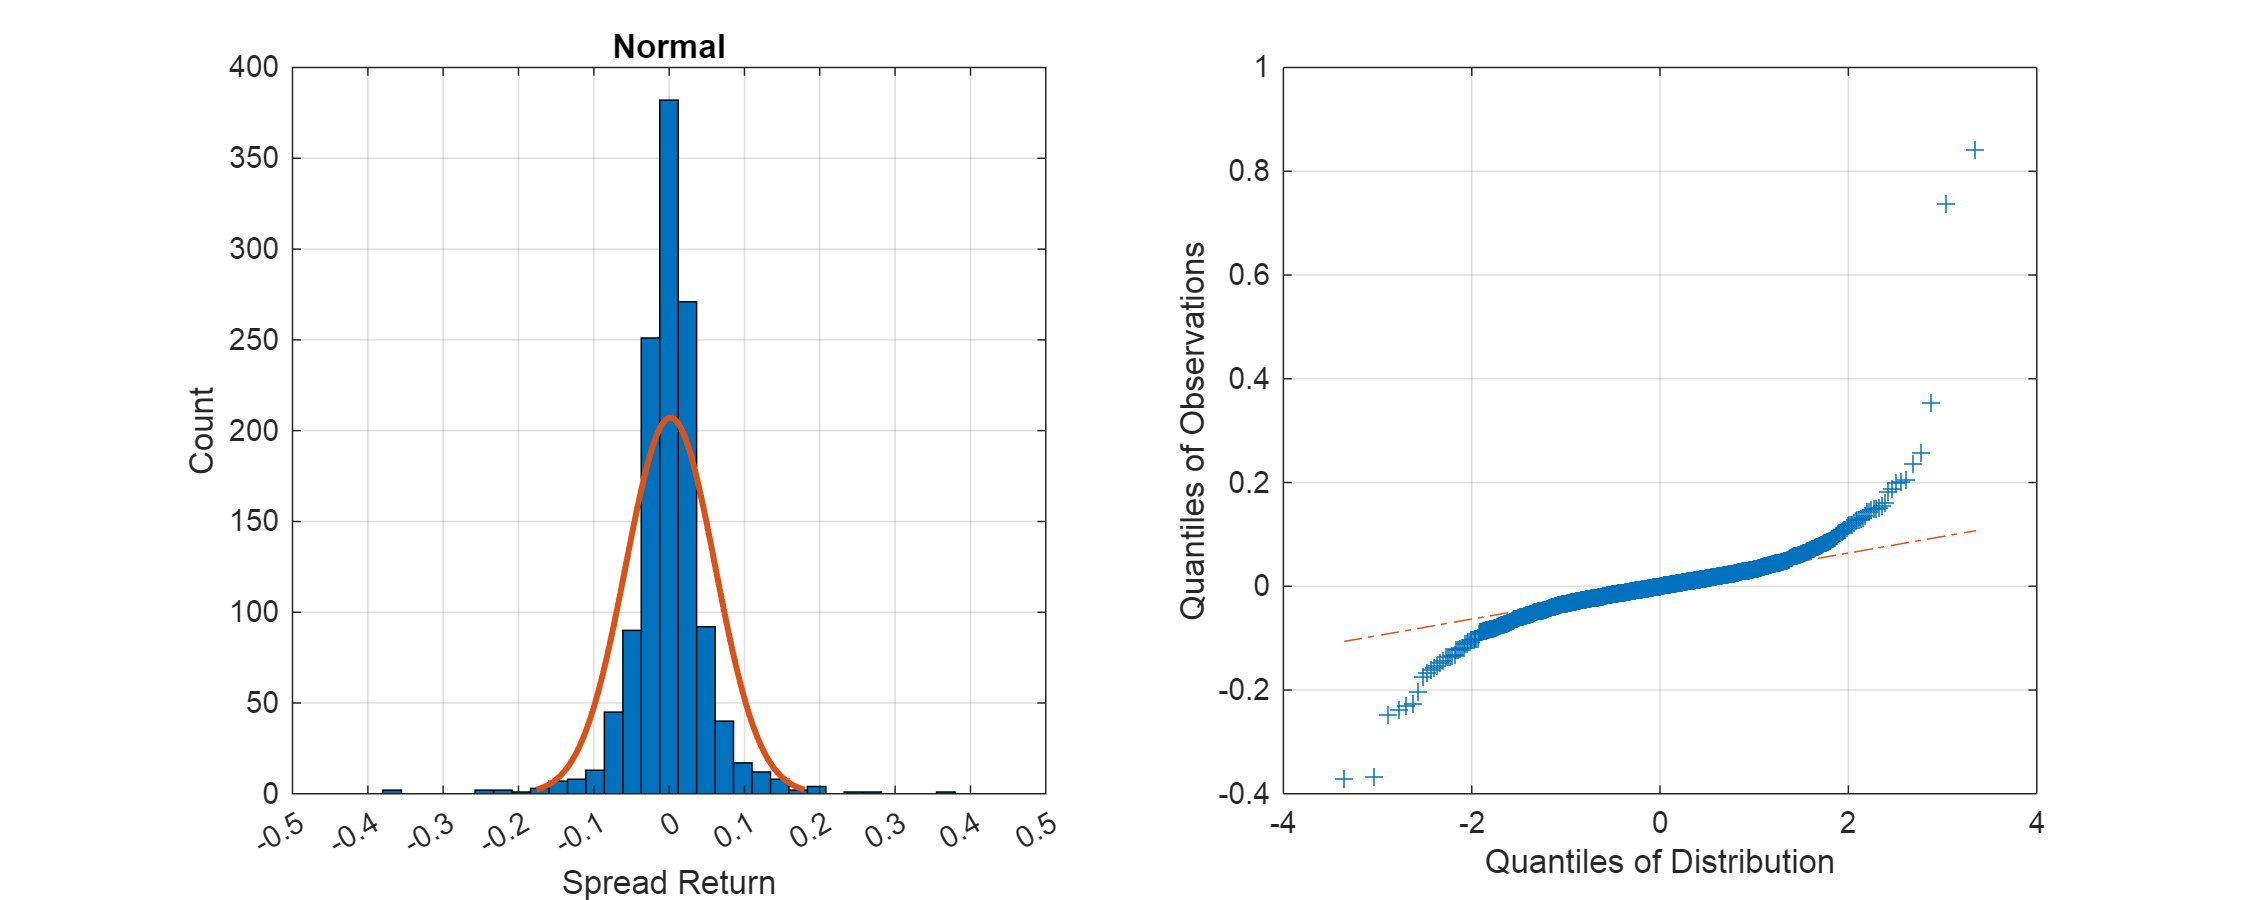

figure()
set(gcf, 'Position', [0 0 1000 400])
 
subplot(1,2,1)
histfit(rSPRD,50,'normal')
set(gca,'XTick',-0.5:0.10:0.5)
xlim([-0.50 +0.50])
title('Normal')
ylabel('Count')
xlabel('Spread Return')
grid on
 
subplot(1,2,2)
qqplot(rSPRD, makedist("Normal"))
title('')
ylabel('Quantiles of Observations')
xlabel('Quantiles of Distribution')
box on
grid on

It is hard to compare what we did in class since we implemented the parametric methods to calculate spread VaR in class while we only need to implement the parametric method to compute Pepsi stock VaR in this homework.